依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

迁移模板时序特征

预加载此脚本一次即可

[MOpCoeff,MOpNtats]=TransferLearning.CoeffNtats("MOp");

统一实验分析作图v17.1.1已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


排序热图2

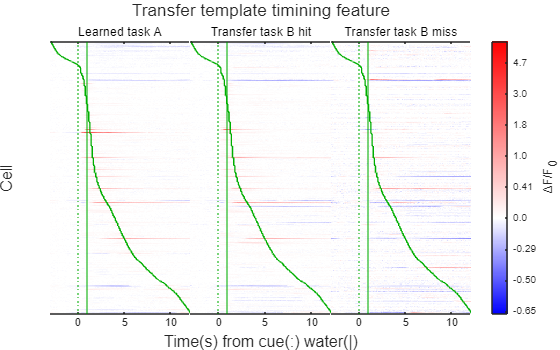

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=MOpNtats.NTATS{:,:,["Learned4_cue1_water","Transfer_cue2_water_hit","Transfer_cue2_water_miss"]};
Data=Data(any(Data,2:3),:,:);
[~,PeakTime]=max(Data(:,:,1),[],2);
[PeakTime,SortIndex]=sort(PeakTime/8-3);
[Layout,Axes]=TransferLearning.BasicHeatmap(Data(SortIndex,:,:),["Learned task A","Transfer task B hit","Transfer task B miss"],Colors,false);
Ys=1:height(Data);
for A=1:numel(Axes)
	line(Axes(A),PeakTime,Ys,Color=Colors(3,:));
end
title(Layout,'Transfer template timining feature');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('TimeOrderedTransfer.svg'),'-dsvg');